% Imperial College London
% 2024-25 MRes in Medical Robotics and Instrumentation
% Coursework 01 - Coppelia Tester
% Author: Hongyu Wang

clc;
close all;
clear;

## Configuration

TASK_ID = 2;

switch TASK_ID
    case 2
        joint_trajectory_coppelia = load("task02_angles.csv");
        time_trajectory_coppelia = load("task02_times.csv");
        
    case 3
        joint_trajectory_coppelia = load("task03_angles.csv");
        time_trajectory_coppelia = load("task03_times.csv");
    otherwise
        fprintf("[WARNNING] -- INVALID TASK CHOOSE");
end

config = initConfig();
robot = initRobot(config);

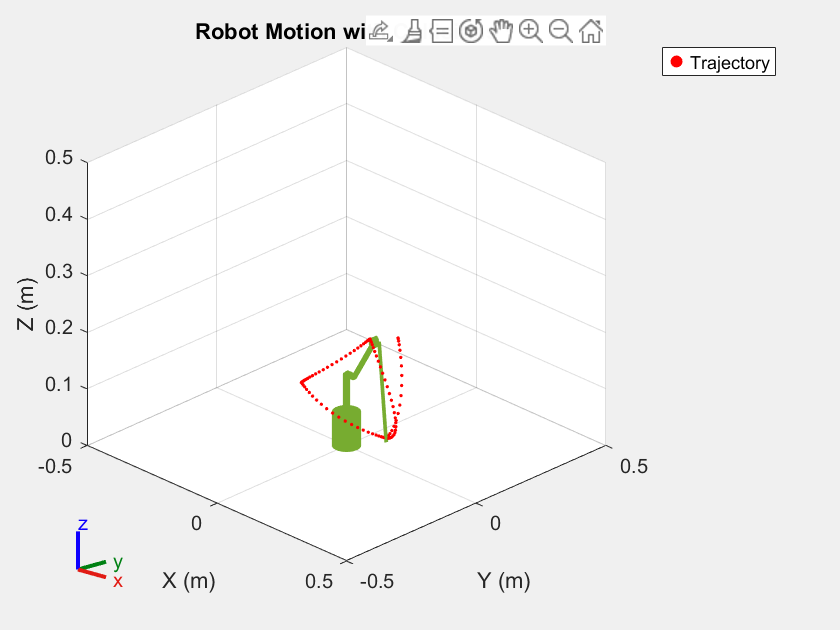

[LOG INFO] -- Simulation complete.


joint_trajectory_matlab = joint_trajectory_coppelia + (config.home_configuration_matlab - config.home_configuration_coppelia);
simulateRobotMATLAB(robot, joint_trajectory_matlab,-1,'collision', 5, true);

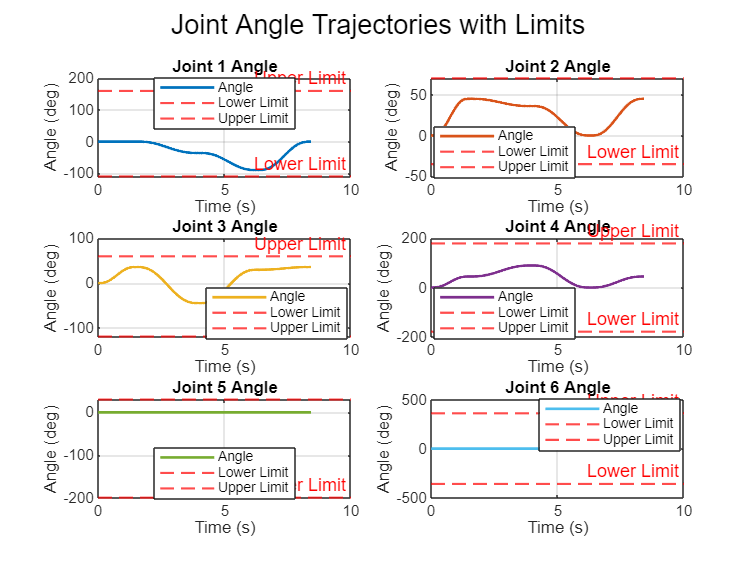

showJointAngleInTrajectory(joint_trajectory_coppelia, config.joint_angle_limits_coppelia, time_trajectory_coppelia);

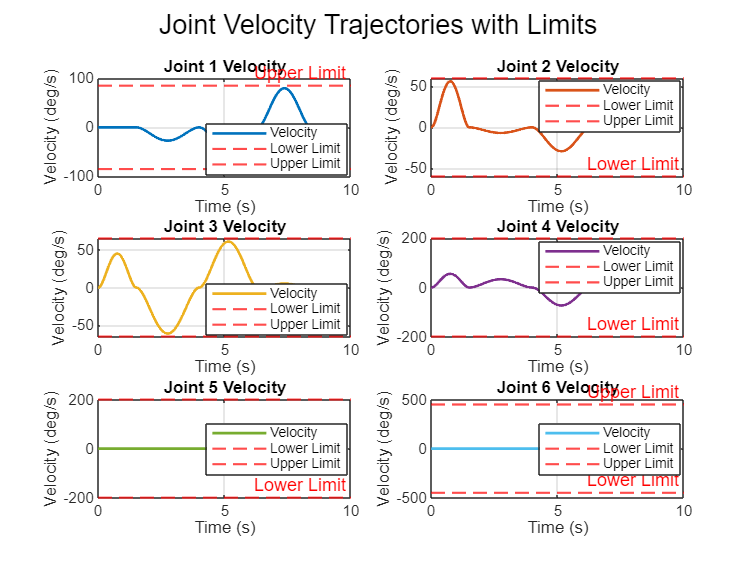

% Calculate joint velocities (numerical derivative of joint angles)
joint_velocity = diff(joint_trajectory_matlab) / (time_trajectory_coppelia(2) - time_trajectory_coppelia(1));  % Velocity = Δθ / Δt
joint_velocity_0 = zeros(1,6);
% Normalize the velocity differences to avoid jumps
for i = 1:size(joint_velocity, 1)
    joint_velocity(i, :) = mod(joint_velocity(i, :) + pi, 2 * pi) - pi;
end
joint_velocity = [joint_velocity_0; joint_velocity];

showJointVelocityInTrajectory(joint_velocity, config.joint_velocity_limits, time_trajectory_coppelia);